clear all
close all
clc

# Spr2023 Final Exam

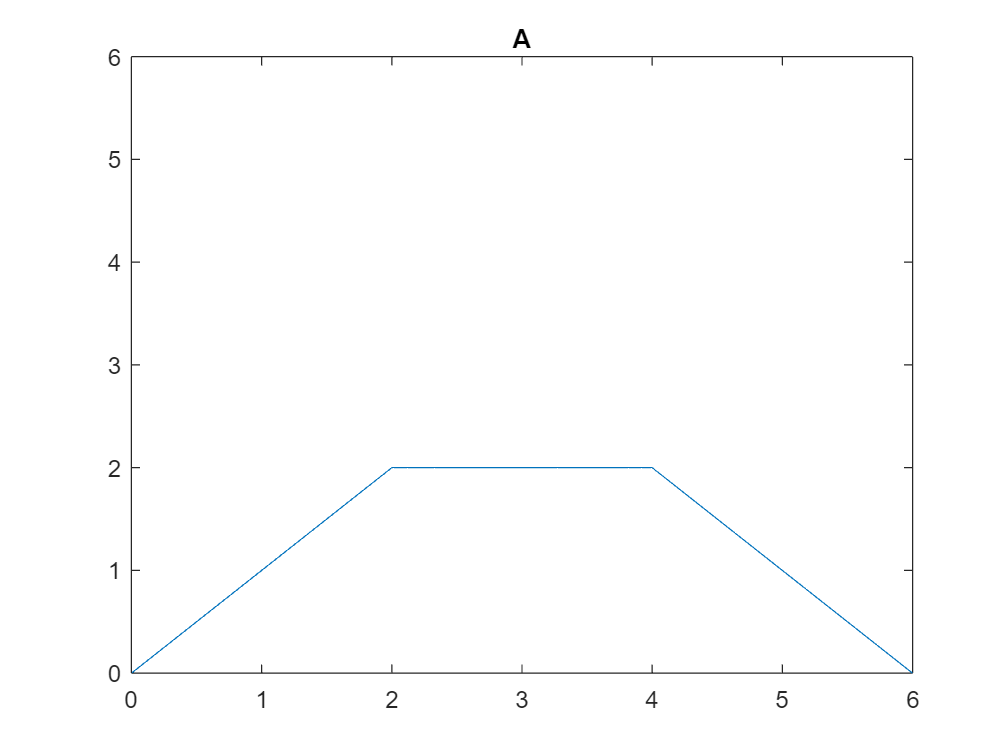

$$ans = t-\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-\mathrm{heaviside}\left(t-4\right)\,\left(t-4\right)+\mathrm{heaviside}\left(t-6\right)\,\left(t-6\right)$$

% a = y3t
syms t
xt = heaviside(t) - heaviside(t-4);
ht = heaviside(t) - heaviside(t-2);
myconvolve(xt,ht,'A',6,6)

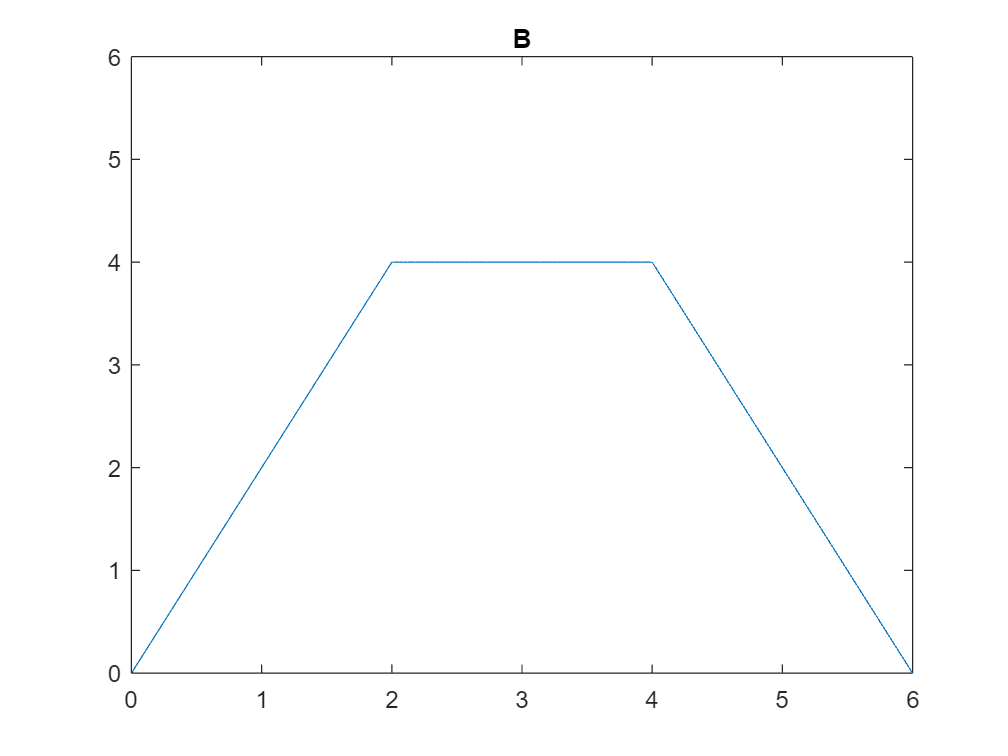

$$ans = 2\,t-2\,\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)-2\,\mathrm{heaviside}\left(t-4\right)\,\left(t-4\right)+2\,\mathrm{heaviside}\left(t-6\right)\,\left(t-6\right)$$


% b = y2t
syms t
xt = heaviside(t) - heaviside(t-4);
ht = 2*(heaviside(t) - heaviside(t-2));
myconvolve(xt,ht,'B',6,6)

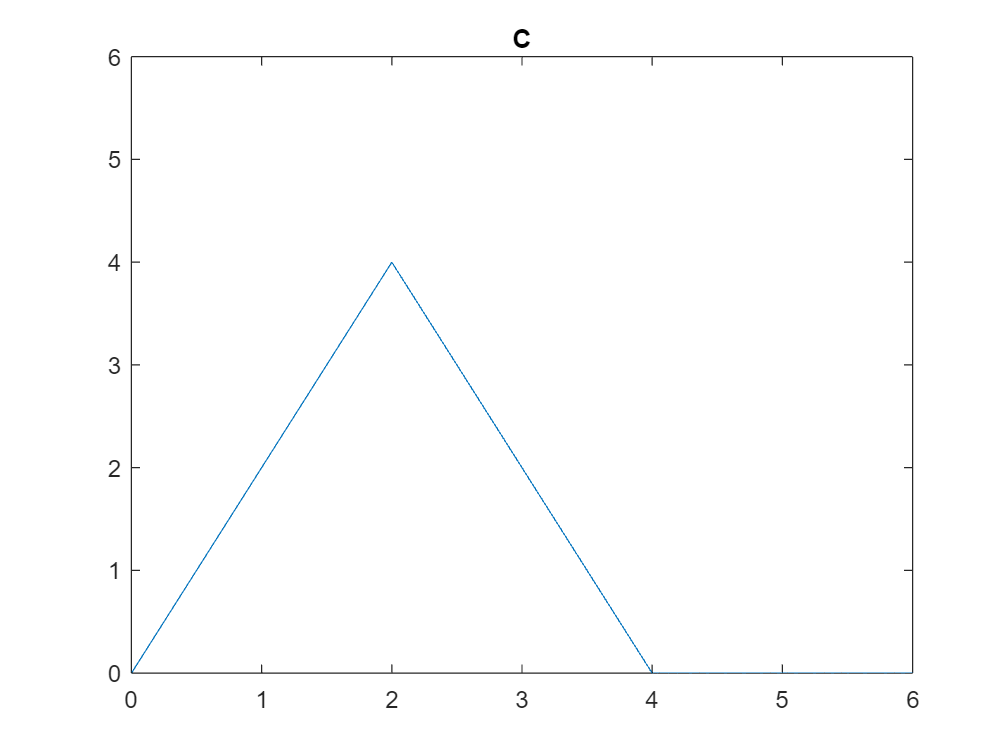

$$ans = 2\,t-4\,\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)+2\,\mathrm{heaviside}\left(t-4\right)\,\left(t-4\right)$$


% c = y1t
syms t
xt = (heaviside(t) - heaviside(t-2))*.5;
ht = 4*(heaviside(t) - heaviside(t-2));
myconvolve(xt,ht,'C',6,6)

# Spr2023 Exam 2

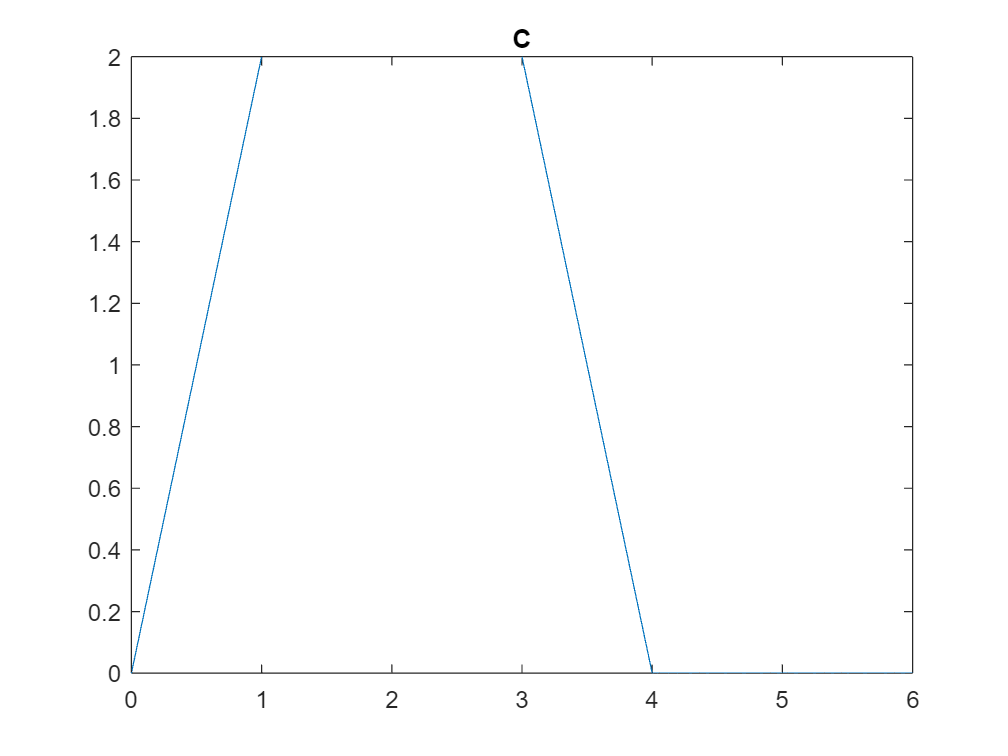

syms t
xt = 2*heaviside(t)-2*heaviside(t-1);
ht = t*heaviside(t)-(t-1)*heaviside(t-1);
ylim([0 2])
hold off

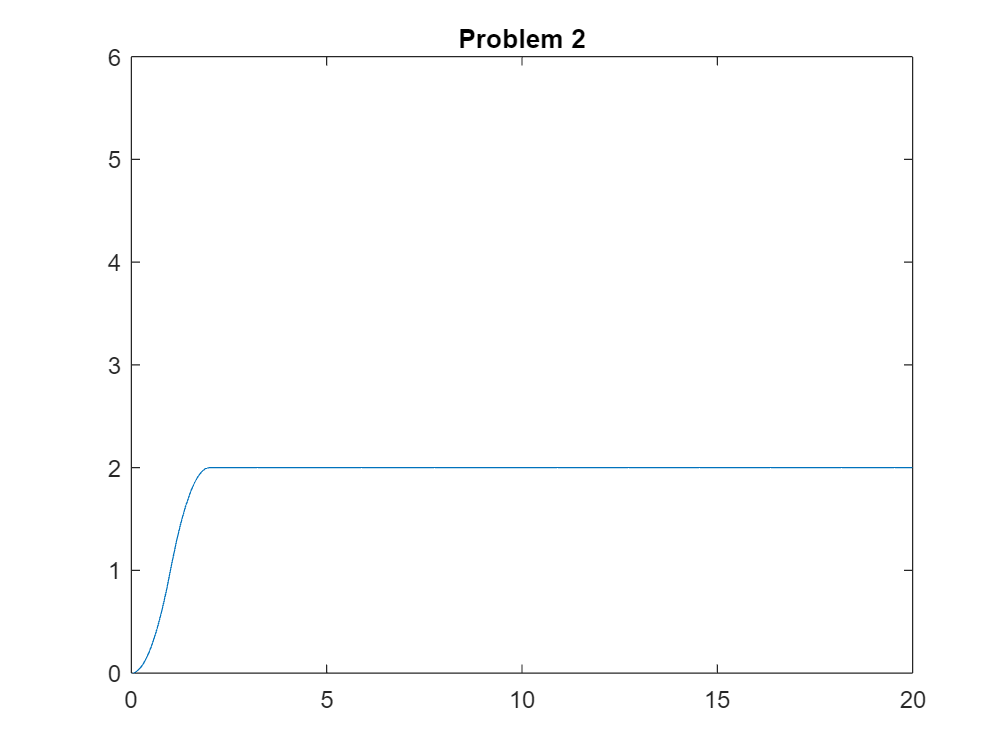

$$eq = \mathrm{heaviside}\left(t-2\right)\,{\left(t-2\right)}^{2}-2\,\mathrm{heaviside}\left(t-1\right)\,{\left(t-1\right)}^{2}+t^{2}$$

eq = myconvolve(xt,ht,'Problem 2',20,6)

# Spr2022 Exam 2

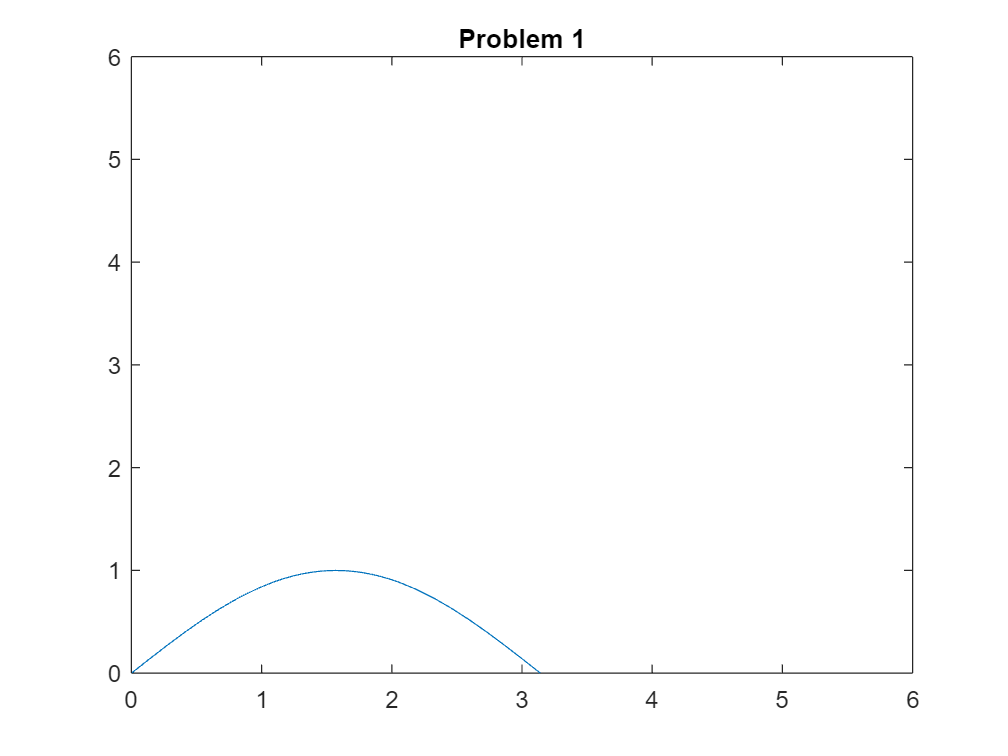

$$eq = \sin\left(t\right)-2\,\sin\left(t\right)\,\mathrm{heaviside}\left(t-2\,\pi \right)+\sin\left(t\right)\,\mathrm{heaviside}\left(t-4\,\pi \right)$$

% Problem 1
syms t
xt = cos(t)*heaviside(t)-cos(t)*heaviside(t-2*pi);
ht = heaviside(t)-heaviside(t-2*pi);
eq = myconvolve(xt,ht,'Problem 1',6,6)

% Problem 2
p1 = -100 + 500*j;
p2 = -100 - 500*j;
transfunc = tfpoles(p1,p2,1,'lp')

transfunc =
 
          260000
  ----------------------
  260000 s^2 + 200 s + 1
 
Continuous-time transfer function.



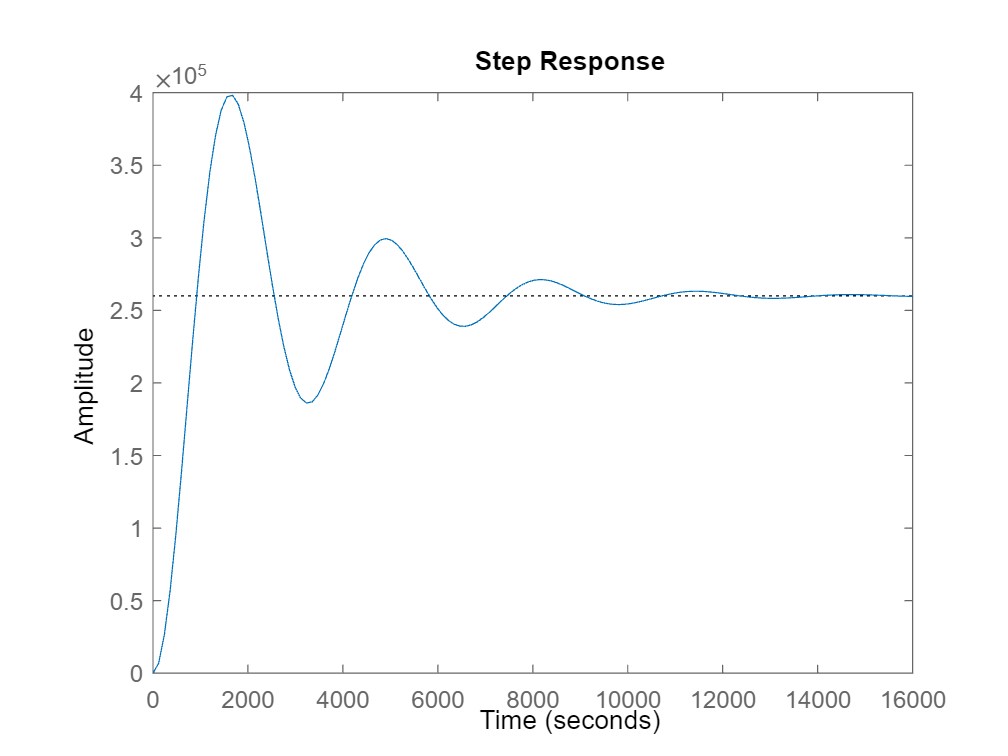

stepplot(transfunc)

# Fal2021 Exam 2

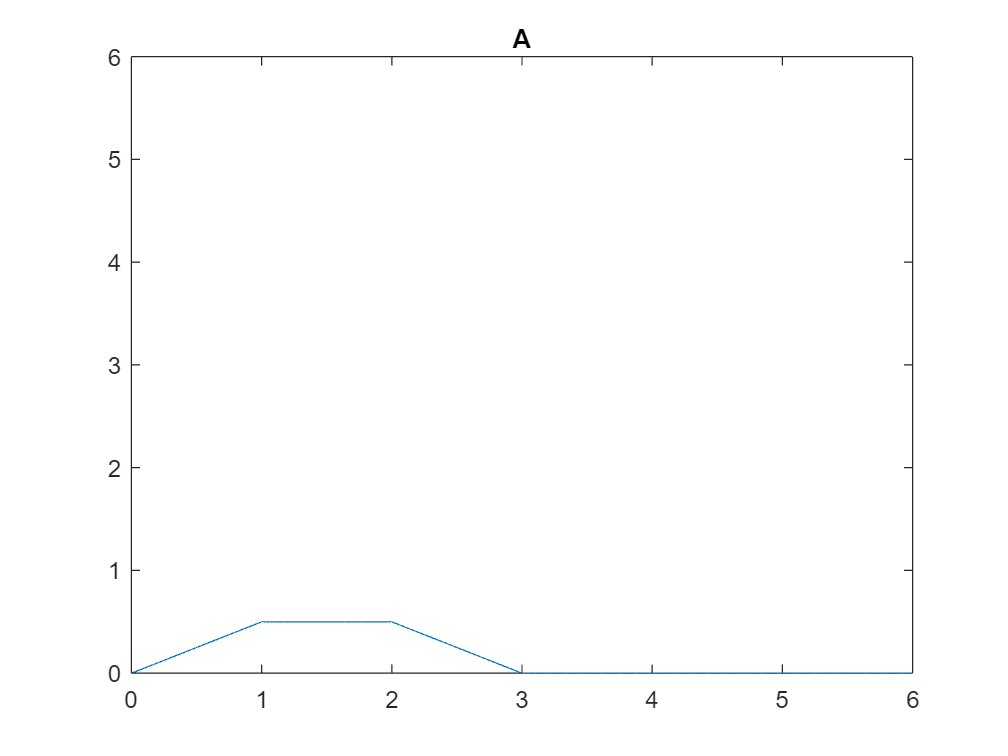

$$eq = \frac{t}{2}-\frac{\mathrm{heaviside}\left(t-1\right)\,\left(t-1\right)}{2}-\frac{\mathrm{heaviside}\left(t-2\right)\,\left(t-2\right)}{2}+\frac{\mathrm{heaviside}\left(t-3\right)\,\left(t-3\right)}{2}$$

% Problem 2
syms t
xt = heaviside(t) - heaviside(t-1);
ht = .5*(heaviside(t) - heaviside(t-2));
eq = myconvolve(xt,ht,'A',6,6)

% Problem 3
syms t s k b m 
Zl = s/k;
Zr = 1/b;
Zc = 1/(m*s);
Zrl = (1/Zl+1/Zr)^-1;
% circuit representation 

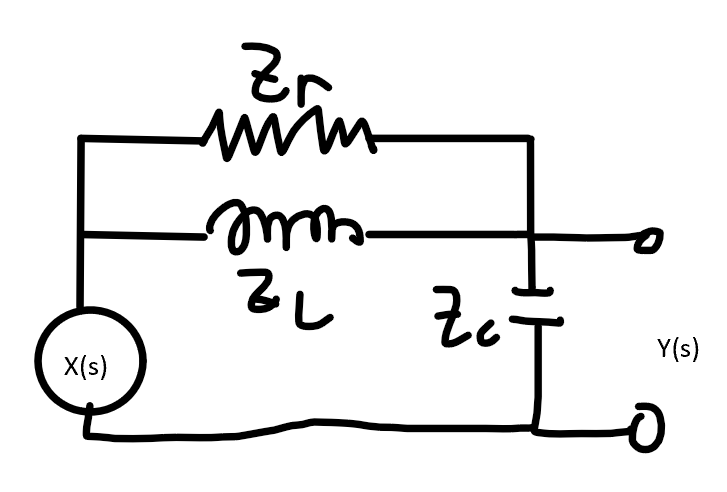

% a

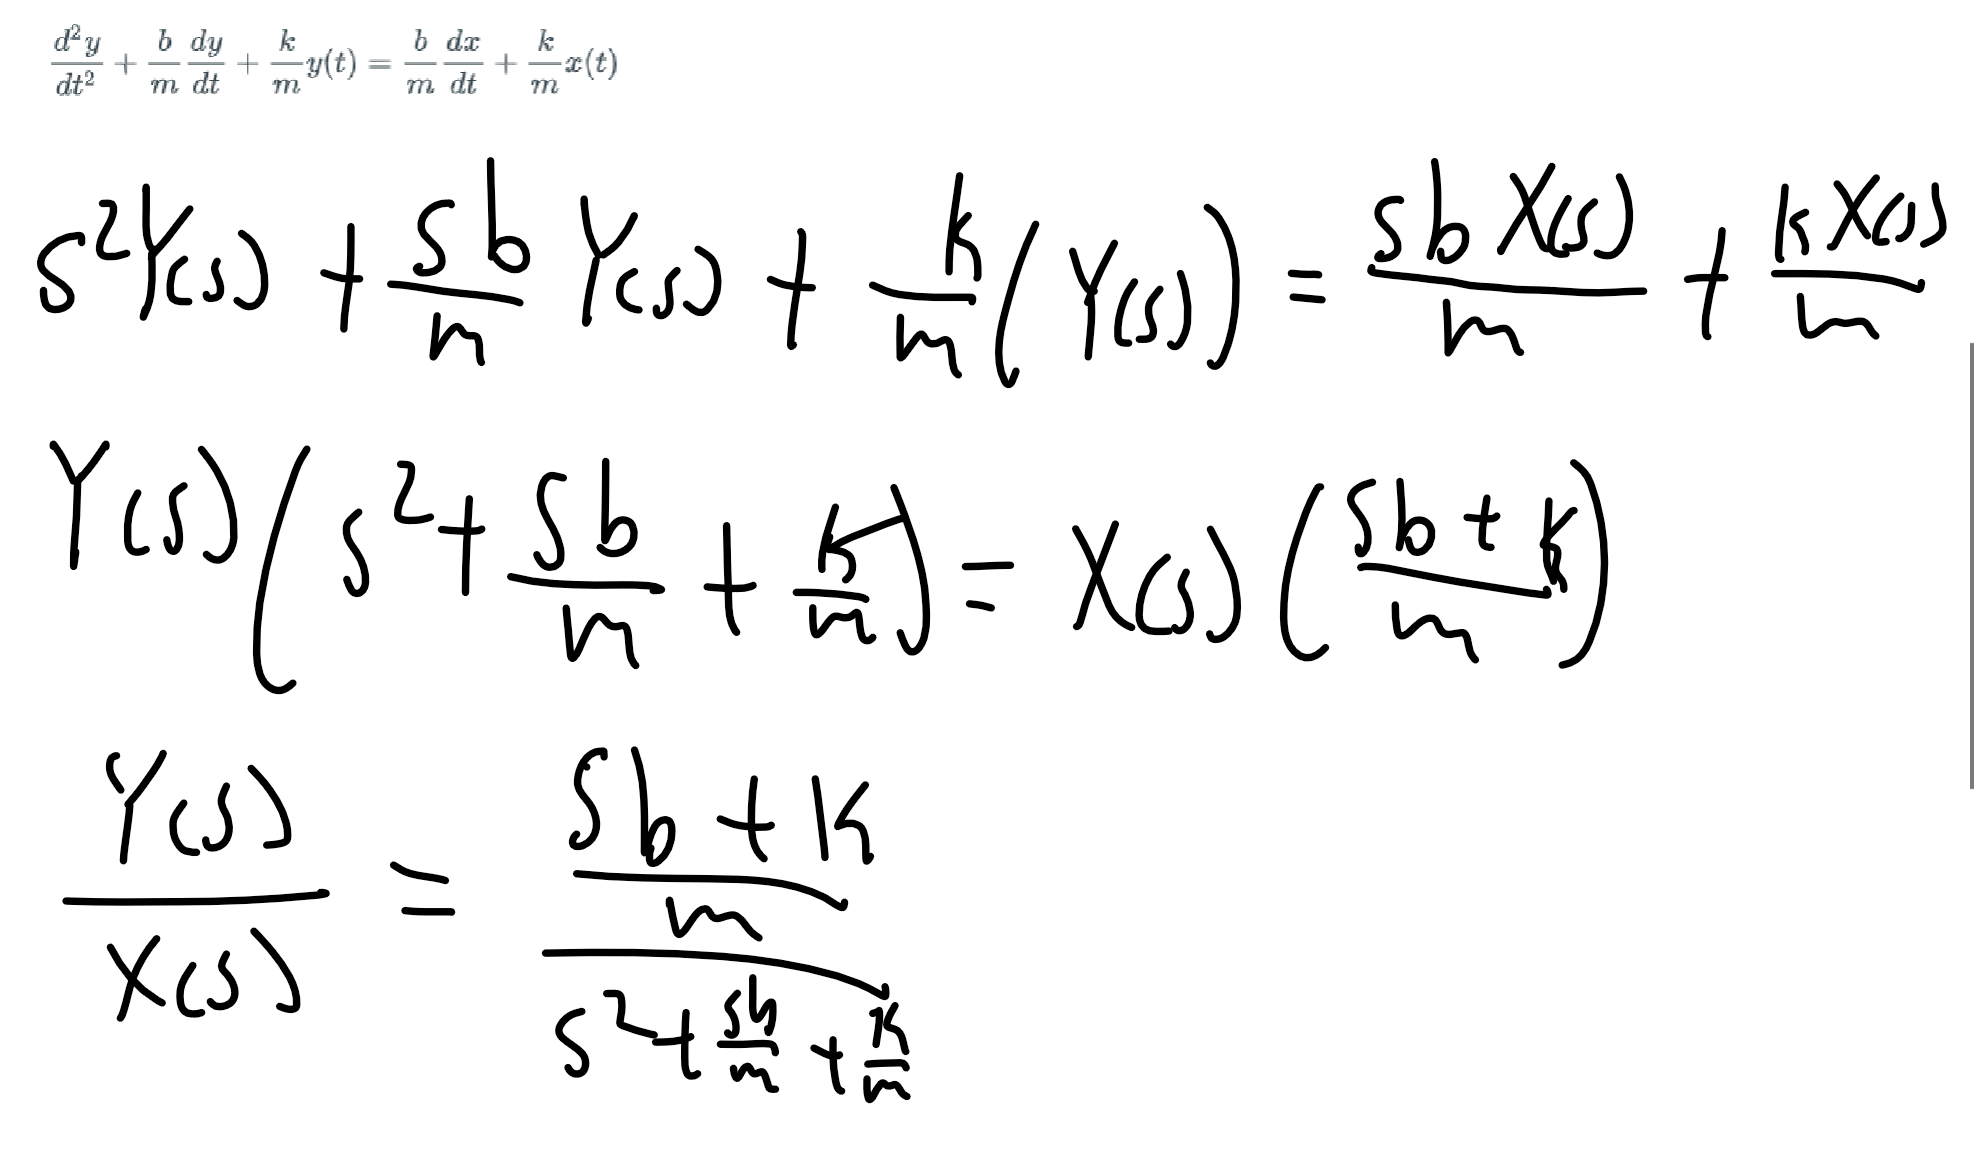

% b 
% low pass filter as the limit as w approaches infinity reaches zero so at
% really high frequencies the filter will spit out smaller and smaller
% values when the limit as w approaches 0 is simply a gain of 1 which we
% assume this system has

% c assumed transfunc if k = 0 B,A,C
Hs_half = tf(1,[.5 1])

Hs_half =
 
      1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



Hs_one = tf(1,[1 1])

Hs_one =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



Hs_three = tf(1,[3 1])

Hs_three =
 
     1
  -------
  3 s + 1
 
Continuous-time transfer function.



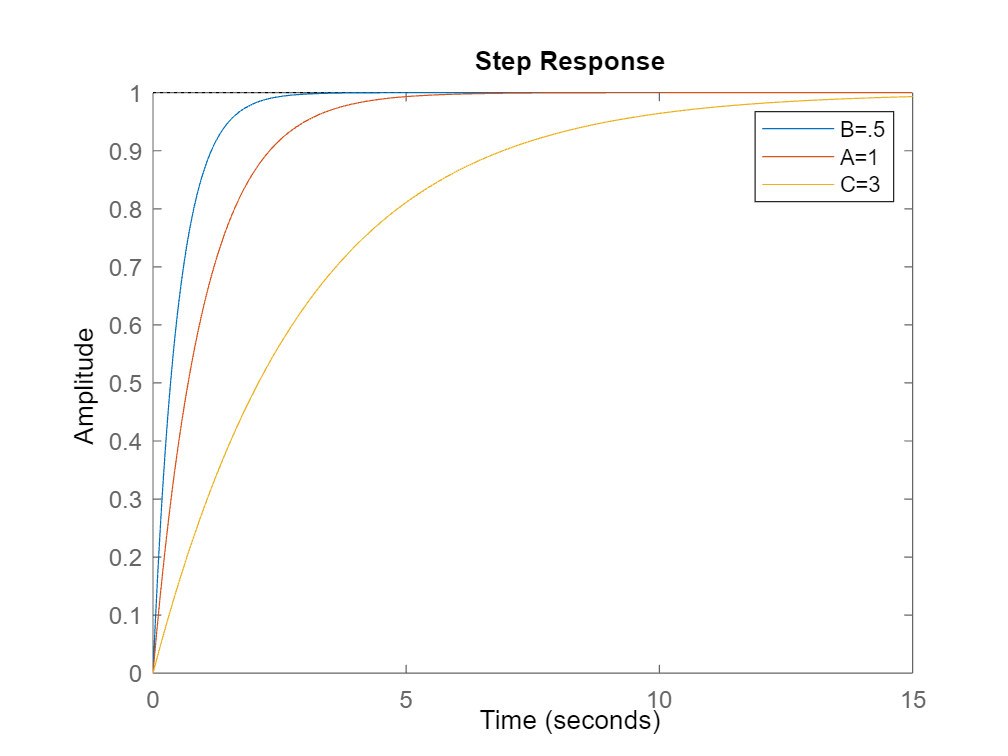

stepplot(Hs_half);
hold on
stepplot(Hs_one);
hold on
stepplot(Hs_three);
hold on
legend('B=.5','A=1','C=3')
xlim([0 15])
hold off


% d 
Hs_half2 = tf(.5,[1 0 .5])

Hs_half2 =
 
     0.5
  ---------
  s^2 + 0.5
 
Continuous-time transfer function.



Hs_one2 = tf(1,[1 0 1]);
Hs_three2 = tf(3,[1 0 3])

Hs_three2 =
 
     3
  -------
  s^2 + 3
 
Continuous-time transfer function.



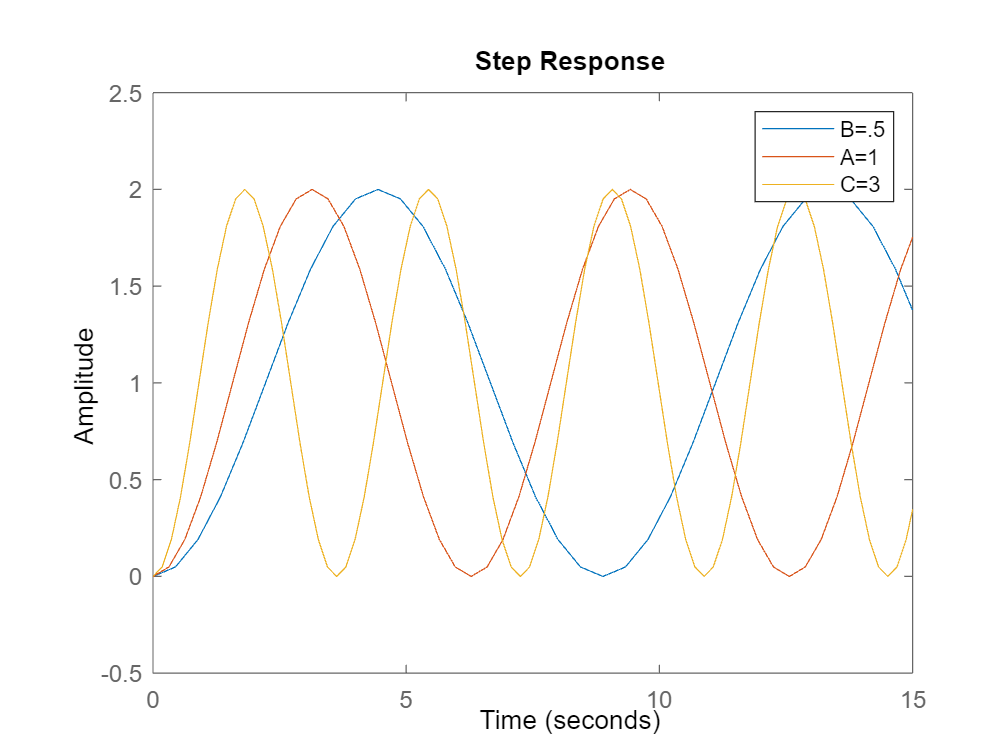

stepplot(Hs_half2)
hold on
stepplot(Hs_one2)
hold on
stepplot(Hs_three2)
hold on
legend('B=.5','A=1','C=3')
xlim([0 15])
hold off

% f
avgspd = 15.5;
avgwidth = .125;
avgf = avgspd/avgwidth

avgf = 124

topspd = 31;
lowwid = .05;
topf = topspd/lowwid

topf = 620

First we have to make a couple assumptions.  Since the road engineer didn't provide us with an average speed and pavement width, we have to assume that the direct middles are the averages so 35 mph for speed and .125 for distance of wavey pavement.  Therefore, we have to assume that around there is where our frequency will lay most of the time.  So we can calculate that frequency as above by butting the spd/width which will give us (m/s)/m = 1/s = f Hz.  We calculated our average frequency at 124 Hz which in my mind completely deters me from selecting design 1 as that is practically design 1's peak resonant frequency and by doing so we would have the driver 's output constantly being amplified.  Between 2 and 3 we are picking between a less extreme output that happens more often (design 2) and a more extreme output that happens less often(design 3).  Given that we don't have any of the statistical information for the design, our best bet is to go with Design 2 as it averages the two so that we don't have to have risk an extreme output.  Also, if we take a loot at our highest frequency for if we have the minimum spacing and the highest speed, we don't even reach the peak resonant frequency for Design 2 so it's a mostly safe bet.

# Fal2020 Final Exam

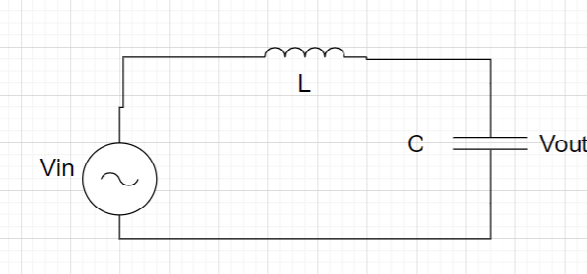

% a
Vx = 1;
syms L C s w
Zl = s*L; % converting to s domain
Zc = 1/(C*s); % converting to s domain
I = Vx/(Zl+Zc); % finding current of system when impulse goes through
Vout = I*Zc % finding the transfer function by finding the S domain votlage for an impulse response

$$Vout = \frac{1}{C\,s\,\left(L\,s+\frac{1}{C\,s}\right)}$$

sol=solve(0 == 1+s^2*L*C,s) % finding the poles in terms of L and C

$$sol = \left(\begin{array}{c} \frac{1}{\sqrt{-C}\,\sqrt{L}}\\ -\frac{1}{\sqrt{-C}\,\sqrt{L}} \end{array}\right)$$

p = (subs(subs(sol,C,20*10^-6),L,.002)); % finding real poles and separating them out
p1 = p(1)

$$p1 = -\sqrt{500}\,\sqrt{50000}\,\mathrm{i}$$

p2 = p(2)

$$p2 = \sqrt{500}\,\sqrt{50000}\,\mathrm{i}$$

Hs = simplify(1/((s-p1)*(s-p2))); % getting our transfer function in function form the tf
Hw = subs(Hs,s,j*w) % getting frequency response

$$Hw = -\frac{1}{w^{2}-25000000}$$

% c ask questions about this one

by taking the limit of our frequency response at omega => infinity and omega => 0 we can see

that it is actually a low pass filter with a gain of 1/25000000(near 0) so as we

get higher in the frequency we are bound to find our magnitude getting

lower as seen in the plot

% d ask questions about this one as well

i = 10 * 0 dB*cos(2000t) = 10cos(2000t) 

explanation - Got my phase angle from 2e3 frequency on the bottom graph and got the dB from the upper graph at 2e3 frequency.  This is because the circuit has a near perfect pass at this frequency with a phase angle of 0 and a gain of 0

ii = 20 * -15 dB*cos(10000t-180) = -300dB*cos(100000t-180)

explanation - Our signal is being attenuated hear because of the high frequency.  By looking at our graph and knowing that we are expecting an attentuation we see that we have a gain of -15 dB and a phase angle of -180 degrees

iii = 15 * 140 dB * cos(5000t) = 2100dB*cos(5000t)

explanation - Our signal is at its' resonant frequency which means that it's the point that it is getting the most amount of gain.  This is the point where our circuit is going to amplify our signal the most because it is at it's natural frequency.

% e

No there are simply too many errors that could happen from the resistance in the measurement device to just not being able to perfectly replicate that frequency.  We woudl probably be able to get a number that is higher than anywhere else on the frequency spectrum, but not actually be able to get the number we are looking for exactly.

# Spr2021 Final Exam

syms t
xt = heaviside(t+4)-heaviside(t+2)+heaviside(t-2)-heaviside(t-4);
yt = (t+4)*.5*heaviside(t+4)-(t+2)*.5*heaviside(t+2)-(t+1)*.5*heaviside(t+1) +(t-1)*.5*heaviside(t-1)+(t-2)*.5*heaviside(t-2)-(t-4)*.5*heaviside(t-4)-(t-5)*.5*heaviside(t-5)+(t-7)*.5*heaviside(t-7);
Xs = laplace(partfrac(xt))

$$Xs = \frac{{\mathrm{e}}^{-2\,s}}{s}-\frac{{\mathrm{e}}^{-4\,s}}{s}$$

Ys = laplace(partfrac(yt))

$$Ys = \frac{{\mathrm{e}}^{-s}}{2\,s^{2}}+\frac{{\mathrm{e}}^{-2\,s}}{2\,s^{2}}-\frac{{\mathrm{e}}^{-4\,s}}{2\,s^{2}}-\frac{{\mathrm{e}}^{-5\,s}}{2\,s^{2}}+\frac{{\mathrm{e}}^{-7\,s}}{2\,s^{2}}+\frac{1}{2\,s}-\frac{1}{2\,s^{2}}$$

Hs = partfrac(Ys/Xs)

$$Hs = \frac{1}{2\,{\mathrm{e}}^{-2\,s}-2\,{\mathrm{e}}^{-4\,s}}+\frac{{\mathrm{e}}^{-s}+{\mathrm{e}}^{-2\,s}-{\mathrm{e}}^{-4\,s}-{\mathrm{e}}^{-5\,s}+{\mathrm{e}}^{-7\,s}-1}{s\,\left(2\,{\mathrm{e}}^{-2\,s}-2\,{\mathrm{e}}^{-4\,s}\right)}$$

ht = ilaplace(Hs)

$$ht = \mathrm{ilaplace}\left(\frac{1}{2\,{\mathrm{e}}^{-2\,s}-2\,{\mathrm{e}}^{-4\,s}},s,t\right)-\frac{\mathrm{heaviside}\left(t+4\right)\,\left\lfloor \frac{t}{2}+2\right\rfloor }{2}+\frac{\mathrm{heaviside}\left(t-2\right)\,\mathrm{heaviside}\left(t+2\right)\,\left\lfloor \frac{t}{2}+1\right\rfloor }{2}+\frac{\mathrm{heaviside}\left(t-1\right)\,\mathrm{heaviside}\left(t+3\right)\,\left\lfloor \frac{t}{2}+\frac{3}{2}\right\rfloor }{2}-\frac{\mathrm{heaviside}\left(t-1\right)\,\mathrm{heaviside}\left(t-5\right)\,\left\lfloor \frac{t}{2}-\frac{1}{2}\right\rfloor }{2}+\frac{\mathrm{heaviside}\left(t-3\right)\,\mathrm{heaviside}\left(t-7\right)\,\left\lfloor \frac{t}{2}-\frac{3}{2}\right\rfloor }{2}-\frac{\left\lfloor \frac{t}{2}\right\rfloor \,\mathrm{heaviside}\left(t-4\right)\,\mathrm{heaviside}\left(t\right)}{2}$$

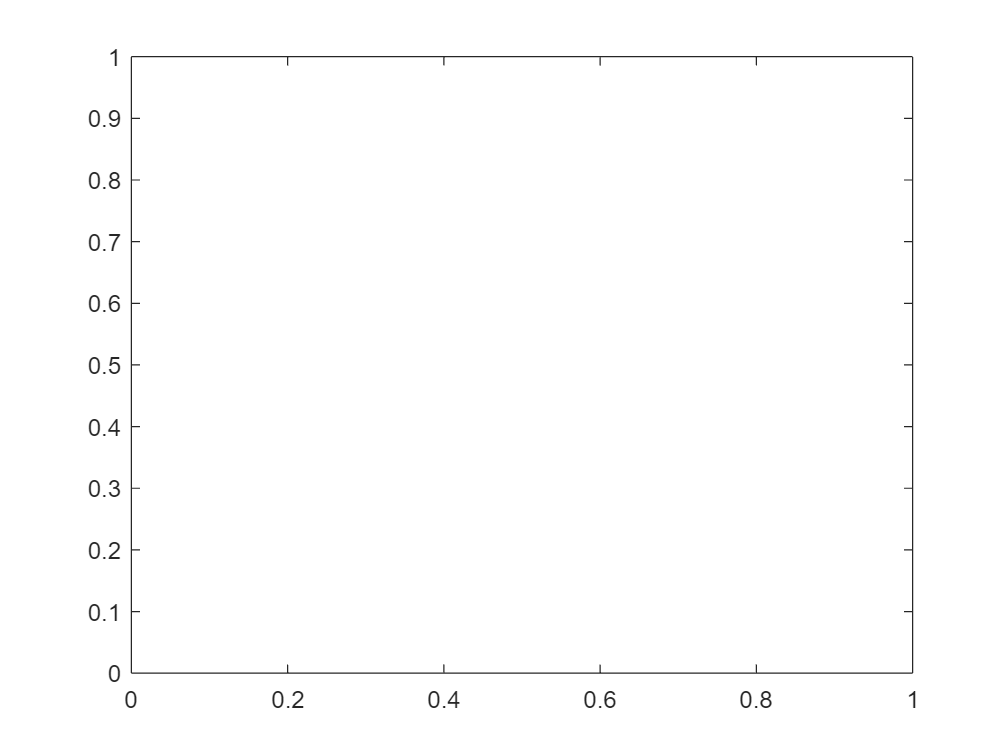



fplot(ht)

# Convolution function

function [pl] = myconvolve(xt,ht,string,x_lim,y_lim)
    pl = ilaplace(laplace(xt)*laplace(ht));
    fplot(pl,[0 x_lim]);
    ylim([0,y_lim])
    title(string)
    hold off
end

# Finding Transfer Function With Poles

function[Hs]=tfpoles(pole1,pole2,gain,string)
    syms A s
    eq1 = A*gain/((s-pole1)*(s-pole2));
    if string =='lp' 
        eq = limit(eq1,s,0,'right')==1;
        sol = double(solve(eq,A));
        transf = subs(eq1,A,sol);
    
    elseif string =='hp'
     eq = limit(eq1,s,inf,'left')==1;
        sol = double(solve(eq,A));
        transf = subs(eq1,A,sol);
    else
        return
    end
    [n, d]=numden(transf);
    coeffs_n=fliplr(double(coeffs(n,'All')));
    coeffs_d=fliplr(double(coeffs(d,'All')));
    Hs=tf(coeffs_n,coeffs_d);
    return
end

# Converting From Transfer Function From Solve To Transfer Function Data Type

function[mytransf]=totf(transf)    
    [n, d]=numden(transf);
    coeffs_n=fliplr(double(coeffs(n,'All')));
    coeffs_d=fliplr(double(coeffs(d,'All')));
    mytransf=tf(coeffs_n,coeffs_d);
    return
end